# FILE PER IL CALCOLO DEL PUNTEGGIO DEL CONTROLLORE PROGETTATO

clear all
close all
clc
nome_gruppo = "Gruppo G";

%settaggio dei valori di accelerazione massima e di rest time
max_acc = 5;
rest_time = 0.2;%simula la fase di pick

%settaggio path per i controllori e per i modelli
addpath("controllori")
addpath("modelli")

%caricamento dei parametri per il controllo dei due giunti
load file_mat_init\ctrl1.mat
load file_mat_init\ctrl2.mat


%creazione sistema
system = ElasticRoboticSystem();
st = system.getSamplingPeriod;
cs = ControlledSystemScara(system,nome_gruppo);



#### Uscite

nr_output = system.getOutputNumber;
for i=1:nr_output
    fprintf('Output %d: %s\n',i,system.getOutputName{i});
end

Output 1: position_1
Output 2: position_2
Output 3: velocity_1
Output 4: velocity_2


#### Ingressi

nr_input = system.getInputNumber;
u_max = system.getUMax;
for i=1:nr_input
    fprintf('Input %d: %s val_max: %f\n',i,system.getInputName{i},u_max(i));
end

Input 1: torque_1 val_max: 600.000000
Input 2: torque_2 val_max: 600.000000


## creazione controllore

ctrl = CascadeController(st,@idynRigid,...
                Kp1_pos,Kp1_vel,Ki1_vel,Kaw1,...
                Kp2_pos,Kp2_vel,Ki2_vel,Kaw2,...
                Wn_notch1,xci_z1,xci_p1,...
                Wn_notch2,xci_z2,xci_p2,...
                Tf1_pos,Tf1_vel,...
                Tf2_pos,Tf2_vel);

cs.setController(ctrl);

ans =   CascadeController with properties:

    PI1vel_Fn_Fpb: [1×1 PI_FN_FBP]
        P1pos_Fpb: [1×1 P_FPB]
    PI2vel_Fn_Fpb: [1×1 PI_FN_FBP]
        P2pos_Fpb: [1×1 P_FPB]
            model: @idynRigid


%settaggio parametri del sistema 
cs.setMaxAcceleration(max_acc);
cs.setRestTime(rest_time);
cs.moveTo([0 0]); % cambia punto di lavoro


###  simulo il sistema per la valutazione

###  "fast"     --> fa 5 esecuzioni

###  "complete" --> fa 5 x 5 esecuzioni (modalità esame)

tic
[score,results] = cs.evalution("fast");

iteration 1, score = 32.807243
iteration 2, score = 32.800843
iteration 3, score = 32.817562
iteration 4, score = 32.803940
iteration 5, score = 32.841328


computation_time = toc;
simulated_time = sum([results.Ttot]);
fprintf('Real-time factor = %f\n',simulated_time/computation_time)

Real-time factor = 0.955418


### grafico i risultati

fprintf('lo score è %f\n',score);

lo score è 32.814183


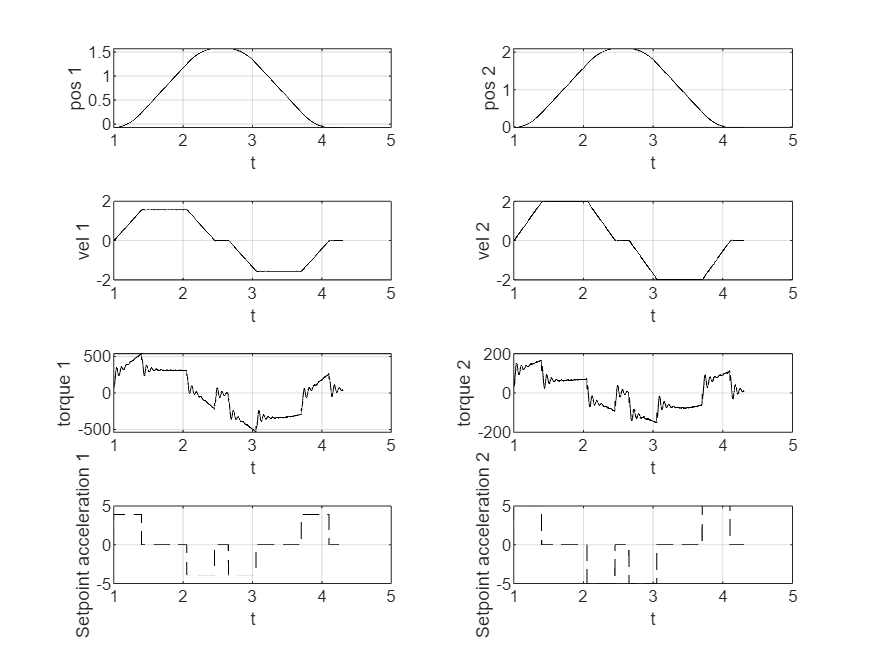

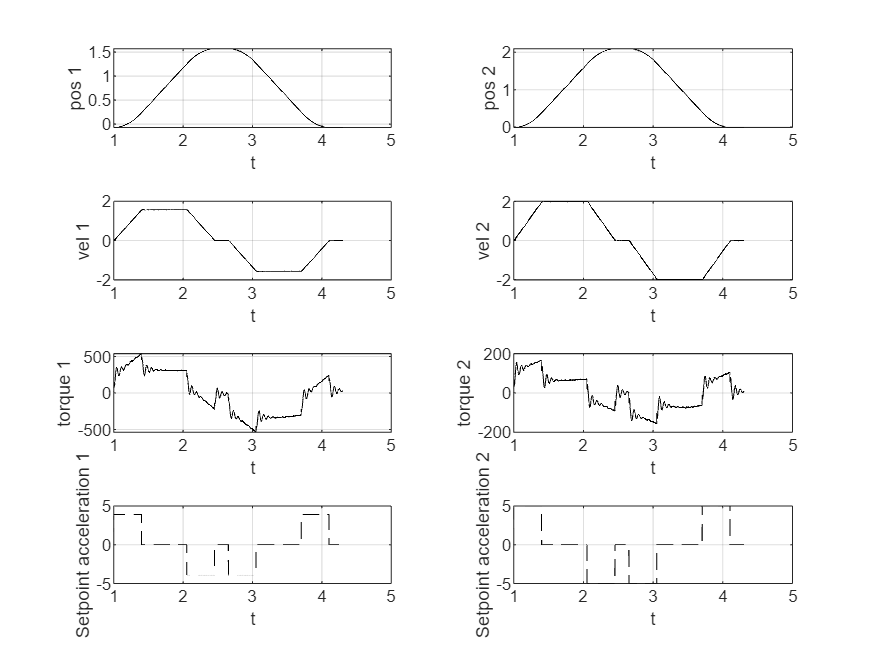

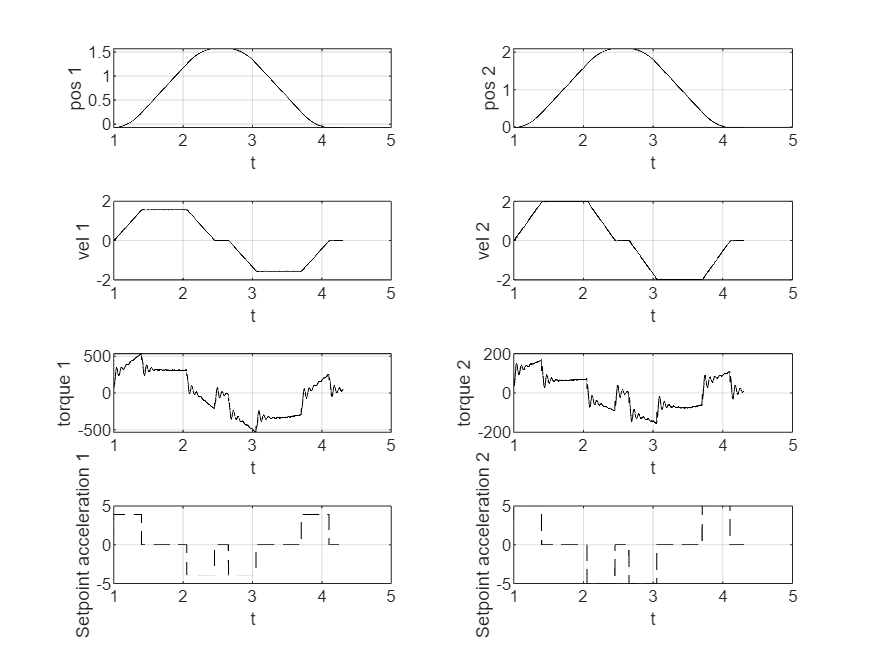

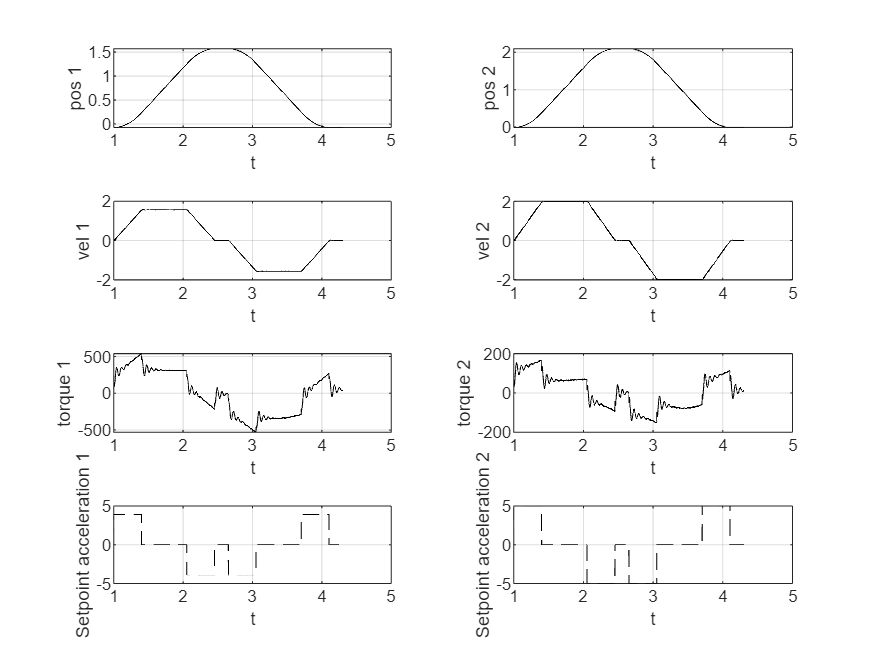

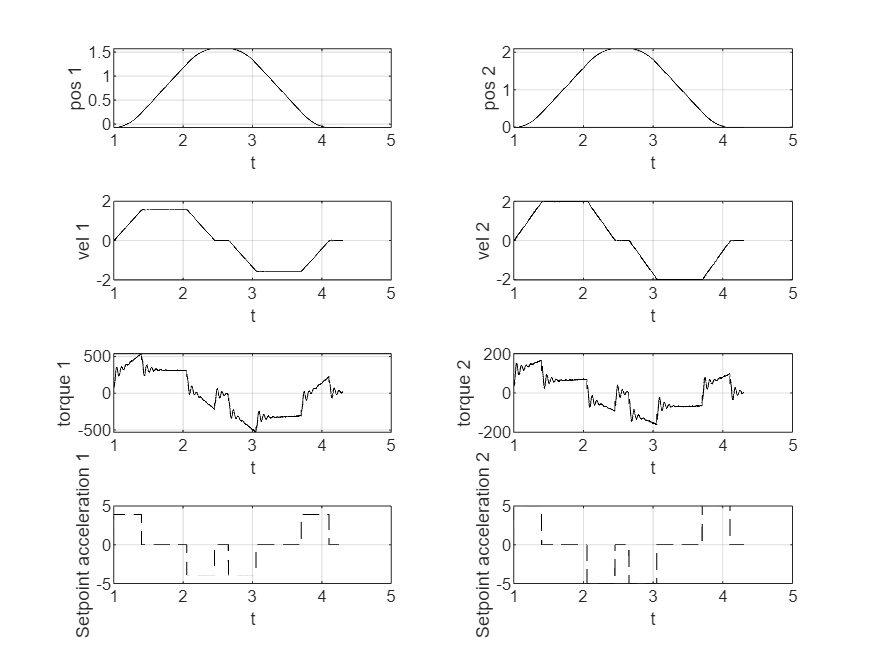

warning off
cs.showResults(results)